# PROBLEM SET 7 - QUESTION 2

We start by stating the positions of each node in our rectangle element:

clear
xy_bar = [0,0;1,0;1,1;0,1];
vpa(xy_bar)

$$ans = \left(\begin{array}{cc} 0 & 0\\ 1.0 & 0\\ 1.0 & 1.0\\ 0 & 1.0 \end{array}\right)$$

Next, we use the following shape functions:

syms xi real
syms eta real
N(1) = 1/4 * (1-xi)*(1-eta);
N(2) = 1/4 * (1+xi)*(1-eta);
N(3) = 1/4 * (1+xi)*(1+eta);
N(4) = 1/4 * (1-xi)*(1+eta);

The Jacobian matrix is obtained as follows:

% Jacobian
J = 1/4 * [eta-1,1-eta,1+eta,-1-eta;xi-1,-xi-1,1+xi,1-xi]*xy_bar

$$J = \left(\begin{array}{cc} \frac{1}{2} & 0\\ 0 & \frac{1}{2} \end{array}\right)$$

With the following determinant and inverse:

det_J = det(J)

$$det\_J = \frac{1}{4}$$

J_inv = inv(J)

$$J\_inv = \left(\begin{array}{cc} 2 & 0\\ 0 & 2 \end{array}\right)$$

Next, we can use the shape functions and their partial derivatives to form the $H^*$ matrix:

% First GN term:
GN = [diff(N(1),xi),diff(N(2),xi),diff(N(3),xi),diff(N(4),xi);...
      diff(N(1),eta),diff(N(2),eta),diff(N(3),eta),diff(N(4),eta)]

$$GN = \left(\begin{array}{cccc} \frac{\eta }{4}-\frac{1}{4} & \frac{1}{4}-\frac{\eta }{4} & \frac{\eta }{4}+\frac{1}{4} & -\frac{\eta }{4}-\frac{1}{4}\\ \frac{\xi }{4}-\frac{1}{4} & -\frac{\xi }{4}-\frac{1}{4} & \frac{\xi }{4}+\frac{1}{4} & \frac{1}{4}-\frac{\xi }{4} \end{array}\right)$$

H_star = J_inv * GN

$$H\_star = \left(\begin{array}{cccc} \frac{\eta }{2}-\frac{1}{2} & \frac{1}{2}-\frac{\eta }{2} & \frac{\eta }{2}+\frac{1}{2} & -\frac{\eta }{2}-\frac{1}{2}\\ \frac{\xi }{2}-\frac{1}{2} & -\frac{\xi }{2}-\frac{1}{2} & \frac{\xi }{2}+\frac{1}{2} & \frac{1}{2}-\frac{\xi }{2} \end{array}\right)$$

We can place the terms of the $H^*$ matrix in the H matrix as follows:

H = [H_star(1,1),0,H_star(1,2),0,H_star(1,3),0,H_star(1,4),0;...
     0,H_star(2,1),0,H_star(2,2),0,H_star(2,3),0,H_star(2,4);...
     H_star(2,1),H_star(1,1),H_star(2,2),H_star(1,2),H_star(2,3)...
     ,H_star(1,3),H_star(2,4),H_star(1,4)];
vpa(H)

$$ans = \left(\begin{array}{cccccccc} 0.5\,\eta -0.5 & 0 & 0.5-0.5\,\eta & 0 & 0.5\,\eta +0.5 & 0 & -0.5\,\eta -0.5 & 0\\ 0 & 0.5\,\xi -0.5 & 0 & -0.5\,\xi -0.5 & 0 & 0.5\,\xi +0.5 & 0 & 0.5-0.5\,\xi \\ 0.5\,\xi -0.5 & 0.5\,\eta -0.5 & -0.5\,\xi -0.5 & 0.5-0.5\,\eta & 0.5\,\xi +0.5 & 0.5\,\eta +0.5 & 0.5-0.5\,\xi & -0.5\,\eta -0.5 \end{array}\right)$$

Now, we define the displacements vector:

d = [-0.01;0.02;0.05;-0.01;-0.02;0.05;0.04;0.02];
vpa(d)

$$ans = \left(\begin{array}{c} -0.01\\ 0.02\\ 0.05\\ -0.01\\ -0.02\\ 0.05\\ 0.04\\ 0.02 \end{array}\right)$$

With the displacement vector and the H matrix, we can obtain the following expressions for each component of strain:

strains = H*d

$$strains = \left(\begin{array}{c} -\frac{3\,\eta }{50}\\ \frac{3\,\xi }{100}+\frac{3}{100}\\ \frac{3\,\eta }{100}-\frac{3\,\xi }{50}-\frac{1}{100} \end{array}\right)$$

We know the boundaries in the parent coordinate system. So, we can form vector of values for $\xi$ and $\eta$:

xi_1 = -1:0.01:1;
eta_1 = -1:0.01:1;

With these values, we can map using the shape functions to obtain the vector of values in the physical coordinate system:

Size = size(xi_1);
Size = Size(2);
x_coord = N*(xy_bar(1:4,1));
y_coord = N*(xy_bar(1:4,2));
for i = 1:Size
    
    x(i) = subs(x_coord,[xi,eta],[xi_1(i),eta_1(i)]);
    y(i) = subs(y_coord,[xi,eta],[xi_1(i),eta_1(i)]);
    
end
x = double(x);
y = double(y);

Here, we will use two meshgrids. The first will be for the physical coordinate system and will be used in the plots. The second meshgrid will be for the parent coordinate system and will be used for the calculations of strain and displacement:

[xx,yy] = meshgrid(x,y);
[xi_2,eta_2] = meshgrid(xi_1,eta_1);

Now, we evaluate our expressions of strains with the values of $\xi$ and $\eta$:

%strain_xx = -3/50 .* eta_2;
strain_xx = subs(strains(1),eta,eta_2);
strain_yy = (xi_2.* 3/100) + (3/100);
strain_xy = (eta_2.* 3/100) - (xi_2.* 3/50) - 1/100;

Next, we set a number of contours and plot each component of strain:

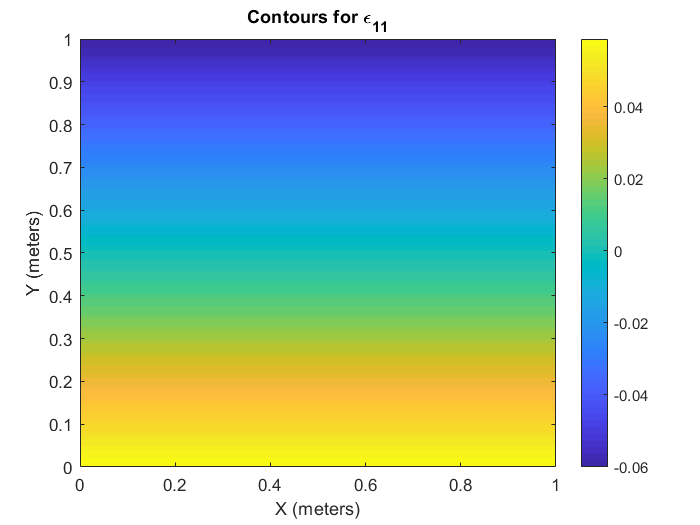

Number = 100;
figure
contourf(xx,yy,strain_xx,Number,'LineColor','none')
colorbar
title('Contours for \epsilon_{11}')
xlabel('X (meters)')
ylabel('Y (meters)')

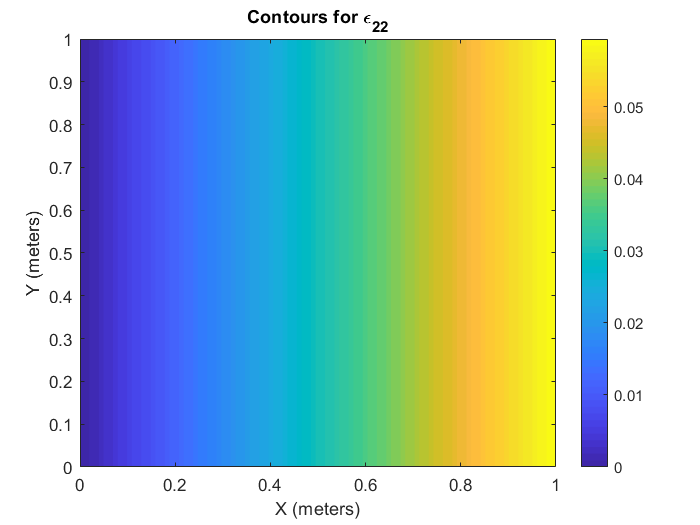

figure
contourf(xx,yy,strain_yy,Number,'LineColor','none')
colorbar
title('Contours for \epsilon_{22}')
xlabel('X (meters)')
ylabel('Y (meters)')

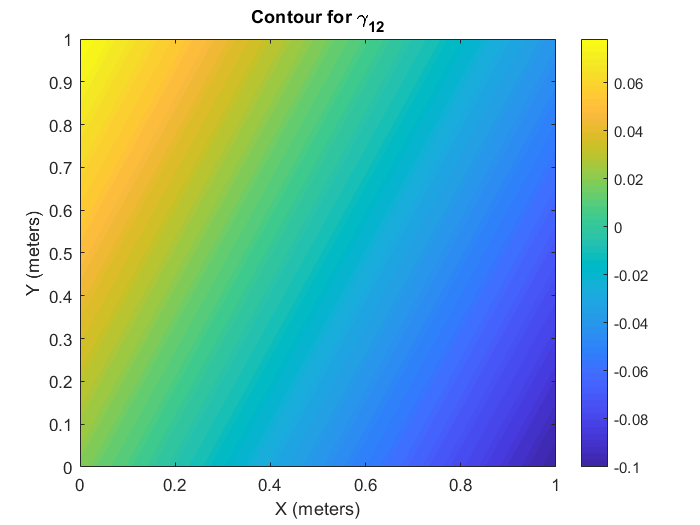

figure
contourf(xx,yy,strain_xy,Number,'LineColor','none')
colorbar
title('Contour for \gamma_{12}')
xlabel('X (meters)')
ylabel('Y (meters)')

For the displacements we follow a similar procedure. We use the shape functions to obtain expressions for displacements $u$ and $v$:

disp = [N(1),0,N(2),0,N(3),0,N(4),0;0,N(1),0,N(2),0,N(3),0,N(4)]*d;
simplify(disp)

$$ans = \left(\begin{array}{c} \frac{3}{200}-\frac{3\,\eta \,\xi }{100}-\frac{\eta }{200}\\ \frac{3\,\eta }{200}+\frac{3\,\eta \,\xi }{200}+\frac{1}{50} \end{array}\right)$$

Then, we can use the same meshgrid with values for $\xi$ and $\eta$ to evaluate these expressions and find the values of both components of displacement:

disp_u = 3/200 - (3/100 .*eta_2.*xi_2) - (eta_2./200); 
disp_v = (3/200 .* eta_2) + (3/200.*eta_2.*xi_2) + 1/50;

Finally, we can plot the two components of displacement as follows:

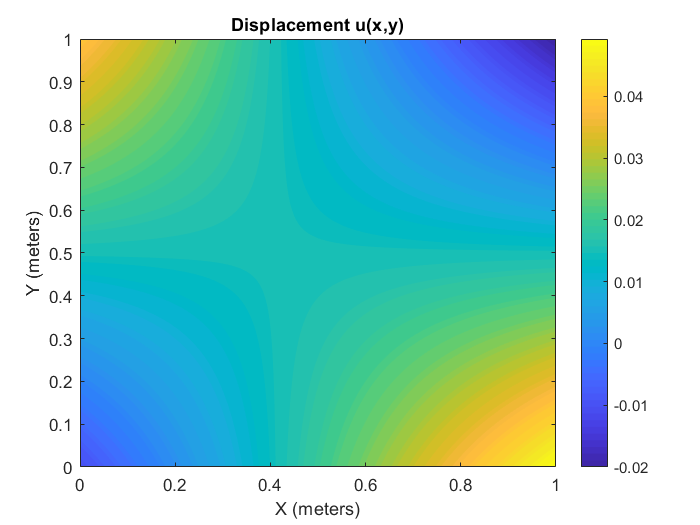

figure
contourf(xx,yy,disp_u,Number,'LineColor','none')
colorbar
title('Displacement u(x,y)')
xlabel('X (meters)')
ylabel('Y (meters)')

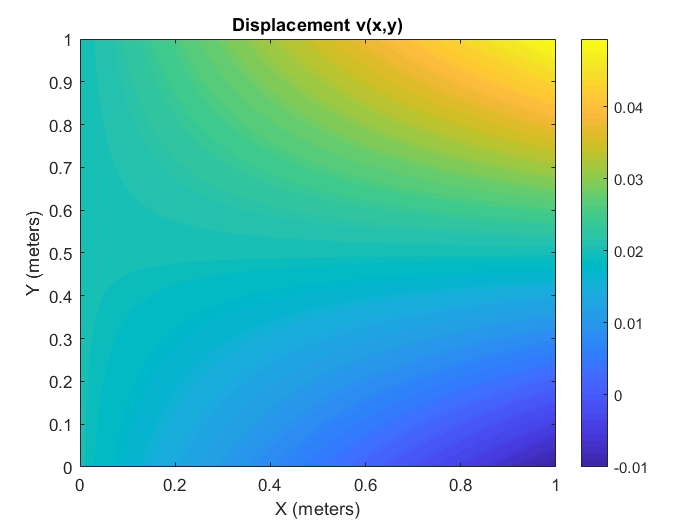

figure
contourf(xx,yy,disp_v,Number,'LineColor','none')
colorbar
title('Displacement v(x,y)')
xlabel('X (meters)')
ylabel('Y (meters)')